## Setting paths

ft_defaults
bml_defaults
format long
addpath('C:\Program Files\SPM\spm12') % added by AM 2024/3/14 because spm functions are required for bml_anat_coord2label()

SUBJECT='sub-DM10XX';
SESSION='intraop'; 
PATH_DATA='Y:/DBS';
PATH_CORTEX = [PATH_DATA '/derivatives/' SUBJECT '/freesurfer/freesurfer'];
PATH_LOC = [PATH_DATA '/derivatives/' SUBJECT '/freesurfer/freesurfer/'];
PATH_ECOGLOC = [PATH_DATA '/derivatives/' SUBJECT '/ecogloc/'];
PATH_PREPROC = [PATH_DATA '/derivatives/' SUBJECT '/preproc'];
PATH_FREESURFER = [PATH_DATA '/derivatives/' SUBJECT '/freesurfer/freesurfer'];
PATH_MNI_BRAIN = 'C:\Program Files\LeadDBS_Classic\leaddbs\templates\space/MNI_ICBM_2009b_NLIN_ASYM/cortex/CortexHiRes.mat';
cd(PATH_PREPROC)

paths = {[PATH_DATA '/derivatives/' SUBJECT '/Herrington_leaddbs_refined'], 
        [PATH_DATA '/derivatives/' SUBJECT '/Herrington_leaddbs'], 
        [PATH_DATA '/derivatives/' SUBJECT '/leaddbs']};
for ip = 1:numel(paths); if isfolder(paths{ip}); PATH_LEADDBS = paths{ip}; break; end; end 

disp(PATH_LEADDBS);

channels = bml_annot_read_tsv([PATH_ANNOT filesep bml_bids_basefname(SUBJECT, SESSION) '_channels.tsv']); 

## === B06a: load ECoG electrode table created in B05 === 

% ECOG_LOC_TABLE = [PATH_LOC filesep SUBJECT '_eleclocalizer-all-landmarks-final.tsv'];
% 
% % loading electrode locations on Left side
% opts = detectImportOptions(ECOG_LOC_TABLE, "FileType","text", "Delimiter", "\t"); 
% landmarks_all = readtable(ECOG_LOC_TABLE, opts); 
% elec = landmarks_all(landmarks_all.coordframe=="recon" & ...
%                      startsWith(landmarks_all.name, 'ecog'), :);
% elec.pos = [elec.sol_pos_1 elec.sol_pos_2 elec.sol_pos_3]; % the final elec solution is stored in position_solution
% % elec = reshape(cell2mat(CortElecLoc),3,length(CortElecLoc))';

## Create lead-DBS electrodes mini-table === 

The following code will help with copying over DBS lead locations, ordered where each row is a lead location (DBS_L1, DBS_L2a, DBS_L2b, ... DBS_L4, DBS_R1... DBS_R4)

reco = load([PATH_LEADDBS filesep 'ea_reconstruction.mat']);
coords = [reco.reco.native.coords_mm{2} reco.reco.mni.coords_mm{2}; 
          reco.reco.native.coords_mm{1} reco.reco.mni.coords_mm{1}]; 
varnames = {'native_x', 'native_y', 'native_z', 'mni_x', 'mni_y', 'mni_z'};
coords = array2table(coords); 
coords.Properties.VariableNames = varnames;


writetable(coords, [PATH_LEADDBS filesep 'ea_reconstruction_coords.tsv'], 'FileType','text', 'Delimiter','\t'); 

## === B06b: create electrodes table (manual) === 

- Create a copy of the subject's channels table in the same annot folder and rename it <subject>_electrodes.tsv. 

- In the new file, retain the first 4 columns (onset, duration, name and type) and delete the remaining columns.

- Delete rows for all non-electrode channels such as blank pins, audio and such.

- For the DBS electrodes, we need to get their native and mni coordinates from the ea_reconstruction.mat file which is an output file of lead DBS (B02). Load the file into MATLAB and open the reco structure. The data of interest is under native and mni for the two coordinate systems respectively. In each case, the 1st cell contains coordinates for the Right electrode and the 2nd cell has coordinates for the Left electrode. When numbering the electrodes, for directed electrodes, use 1, 2A, 2B, 2C, 3A, 3B, 3C and 4. For undirected electrodes, use 1 through number of electrodes.

- For any electrodes that changed position during the experiment, be sure to duplicate their rows as many times as necessary to capture all changes during recordings.

- Calculate the onset and duration in seconds from midnight on the day of the surgery from the implanted and explanted time on the CRF as shown in the example below and populate the first two columns accordingly. If an electrode is not connected during the experiment (as the right DBS electrode below), set onset and duration both to 0.

- For the MER recordings, create as many copies of the electrode as there are stable MER recording locations. The onset and duration values for the MER recordings will be on the CRF but are also saved in a separate table called <subject>_stable_MER. Copy the times over. Only copy stable times that have corresponding depths in the runs table. We only have leaddbs/annot/<subject>_mer_coords.txt coordinates for a subset of time windows (usually those in which we are running a task). 

-   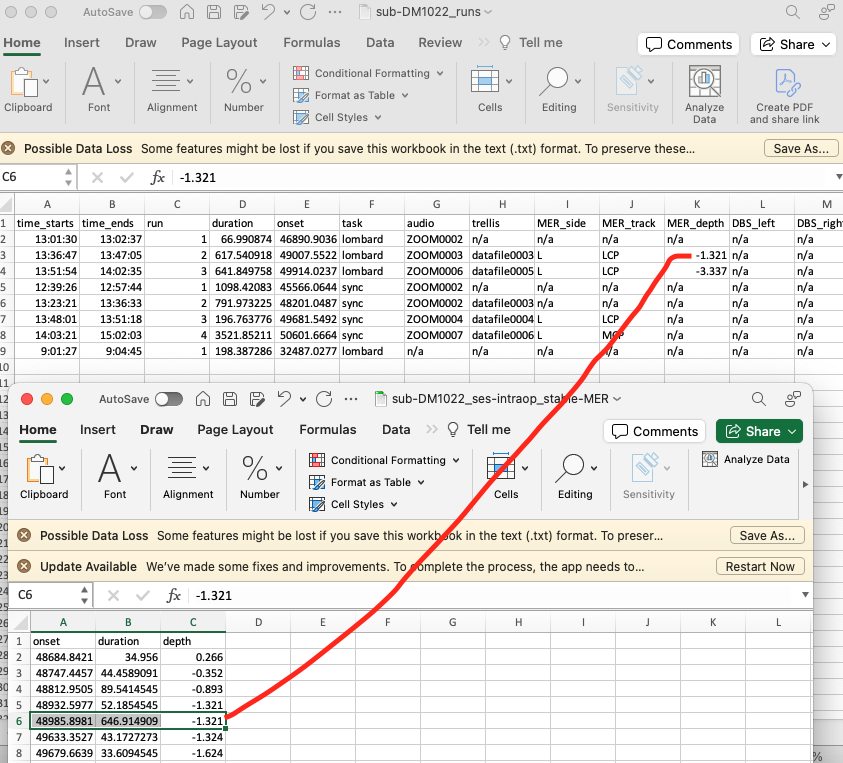

- Create new columns called “native_x”, “native_y” and “native_z” for the x, y and z coordinates of each electrode in the native space. Also create 3 equivalent columns mni_x, y and z for the mni coordinates.

- Copy the native and mni coordinates for the DBS lead and the micro and macros for each depth from the <subject>_mer_coords table present in derivatives/<subject>leaddbs/annot (from B04).

- Copy the native coordinates for the ecog electrodes from the file sub-DM1038_eleclocalizer-all-landmarks-final.tsv. Open the file in Excel. Click the option to 'Format as Table'. Filter by coordfame==recon, then copy all the sol_pos_1, sol_pos_2, sol_pos_3 columns over to the elec table into the native_* columns. 

- Note: Do not copy the MNI coordinates even if they exist. These were likely generated by a brainstorm pipeline and are not always accurate. The rest of this protocol describes how to get them using leaddbs. Save and close the electrodes table.

## === B06c: Transform native coords to mni coords === 

The following lines transforms native coordinates to mni space using leaddbs. keep a copy of each subjects files with each subject also using as a template for subsequent files.


%loading electrode table
electrode = bml_annot_read_tsv([PATH_DATA '/derivatives/' SUBJECT filesep 'annot' filesep SUBJECT '_electrodes.tsv']);

% recalculating mni_nonlinear coords using lead DBS's 
anchor_modality = [PATH_LEADDBS filesep 'anat_t1.nii'];
assert(isfile(anchor_modality),'file %s does not exist',anchor_modality);
warp_file = [PATH_LEADDBS filesep 'glanatInverseComposite.nii.gz'];
assert(isfile(warp_file),'file %s does not exist',warp_file);

leadDBS_mm = [electrode.native_x, electrode.native_y, electrode.native_z]';
leadDBS_mm = [leadDBS_mm; ones(1,size(leadDBS_mm,2))];
[~, leadDBS_vx] = ea_map_coords(leadDBS_mm, anchor_modality);
mni_nonlinear_mm = ea_map_coords(leadDBS_vx, anchor_modality, warp_file,[], 'ANTS',0)';

isCortElec = ismember(electrode.type,{'ECOG'});
electrode(isCortElec,{'mni_x','mni_y','mni_z'}) = ...
    num2cell(mni_nonlinear_mm(isCortElec,1:3));

type= {'ECOG','DBS','SEEG','MICRO'}';
sigma=[1.5,     1,     1,      0.5]';

electrode(:,startsWith(electrode.Properties.VariableNames,'DISTAL'))=[];
cfg=[];
cfg.atlas = 'DISTAL All (Ewert 2017)';
cfg.label_column_basename = 'DISTAL';
cfg.max_assign = 3;
cfg.sigma = bml_map(electrode.type,type,sigma,nan);
cfg.radius = 3;
anat_labels = bml_anat_coord2label(cfg,electrode(:,{'id','mni_x','mni_y','mni_z'}));
electrode = join(electrode,anat_labels);

electrode(:,startsWith(electrode.Properties.VariableNames,'HCPMMP1'))=[];
cfg=[];
cfg.atlas = 'HCPMMP1 (Glasser 2016)';
cfg.label_column_basename = 'HCPMMP1';
cfg.max_assign = 2;
cfg.sigma = bml_map(electrode.type,type,sigma,nan);
cfg.radius = 5;
anat_labels = bml_anat_coord2label(cfg,electrode(:,{'id','mni_x','mni_y','mni_z'}));
electrode = join(electrode, anat_labels);

bml_annot_write_tsv(electrode, [PATH_DATA '/derivatives/' SUBJECT filesep 'annot' filesep SUBJECT '_electrodes.tsv']);
electrode

## Native: Plotting, verifying, and saving for future reference


%Displaying cortex
elec = electrode; 

ld = load([PATH_CORTEX '/cortex_indiv.mat']); 

cortex = reducepatch(ld.cortex.tri, ld.cortex.vert, 0.3)

figure; set(gcf,'Visible','on')

cfg = []; 
cfg.h_ax = gca;
title({[SUBJECT], ' native-space ECoG reconstruction'})
bml_plot3d_surface(cfg, cortex.vertices, cortex.faces); 
elec.x = elec.native_x; elec.y = elec.native_y; elec.z = elec.native_z;
elec.x = elec.x-1; % pull towards the camera for better visualization

cfg.h_ax = gca;
cfg.radius = 1;
[h_points] = bml_plot3d_points(cfg, elec); 


% plot electrodes on cortical surface
% hold on 
% plot3(elec.pos(:,1), elec.pos(:,2), elec.pos(:,3), 'o', 'color', 'r', 'MarkerSize', 15)
% text(elec.pos(:,1), elec.pos(:,2), elec.pos(:,3), elec.name); 

savefig(gcf, [PATH_ECOGLOC filesep SUBJECT '_ses-intraop_ecog-native-interactive']);
exportgraphics(gcf,[PATH_ECOGLOC filesep SUBJECT '_ses-intraop_ecog-native-view-01.png'],'Resolution',600);

## MNI: Plotting, verifying, and saving for future reference

% Plot MNI cortex
elec = bml_annot_read_tsv([PATH_DATA '/derivatives/' SUBJECT filesep 'annot' filesep SUBJECT '_electrodes.tsv']);; 

% load standard MNI brain for plotting
ld = load(PATH_MNI_BRAIN, 'Vertices', 'Faces');

cortex = reducepatch(ld.Faces, ld.Vertices, 0.3); 

figure; set(gcf,'Visible','on')

cfg = []; 
cfg.h_ax = gca;
cfg.surface_facealpha = 0.7; 
title({[SUBJECT], ' MNI-space ECoG reconstruction'})
bml_plot3d_surface(cfg, cortex.vertices, cortex.faces); 
elec.x = elec.mni_x; elec.y = elec.mni_y; elec.z = elec.mni_z;

cfg.h_ax = gca;
cfg.radius = 1;
[h_points] = bml_plot3d_points(cfg, elec); 

savefig(gcf, [PATH_ECOGLOC filesep SUBJECT '_ses-intraop_ecog-mni-interactive']);
exportgraphics(gcf,[PATH_ECOGLOC filesep SUBJECT '_ses-intraop_ecog-mni-view-01.tiff'],'Resolution',300);

## ==== Backup/optional code====

The following lines transforms electrode coordinates and brain surface coordinates from individual space to MNI space Template script. Keep one for each subject Export brainstorm matlab file to matlab as sMRI before running this script

## Loading required objects

% load standard MNI brain for plotting
load(PATH_MNI_BRAIN, 'Vertices', 'Faces');

% load cortical surface 
load([PATH_FREESURFER filesep 'cortex_indiv.mat'], 'cortex');

% load T1 image, freesurfer function MRIread.m required
f = MRIread([PATH_FREESURFER filesep 'mri\T1.nii']);

% load in sMRI if not already in the workspace
%load([PATH_FREESURFER filesep 'sMRI_' SUBJECT])

% vox2ras transformation matrix
vox2ras = [1,0,0,-128;0,1,0,-128;0,0,1,-128;0,0,0,1];

## debugging non-appearance of hcpmmp1 atlas labels

figure; % MNI electrode plotted with MNI brain
Hp = patch('vertices', Vertices,'faces', Faces,...
    'facecolor',[.50 .50 .50],'edgecolor','none',...
    'facelighting', 'gouraud', 'specularstrength', .50);
camlight('headlight','infinite');
axis off; axis equal
alpha 0.5
hold on; plot3(mni_nonlinear_mm(1:126,1), mni_nonlinear_mm(1:126,2), mni_nonlinear_mm(1:126,3), 'b.', 'MarkerSize', 15)